# **两次优化**

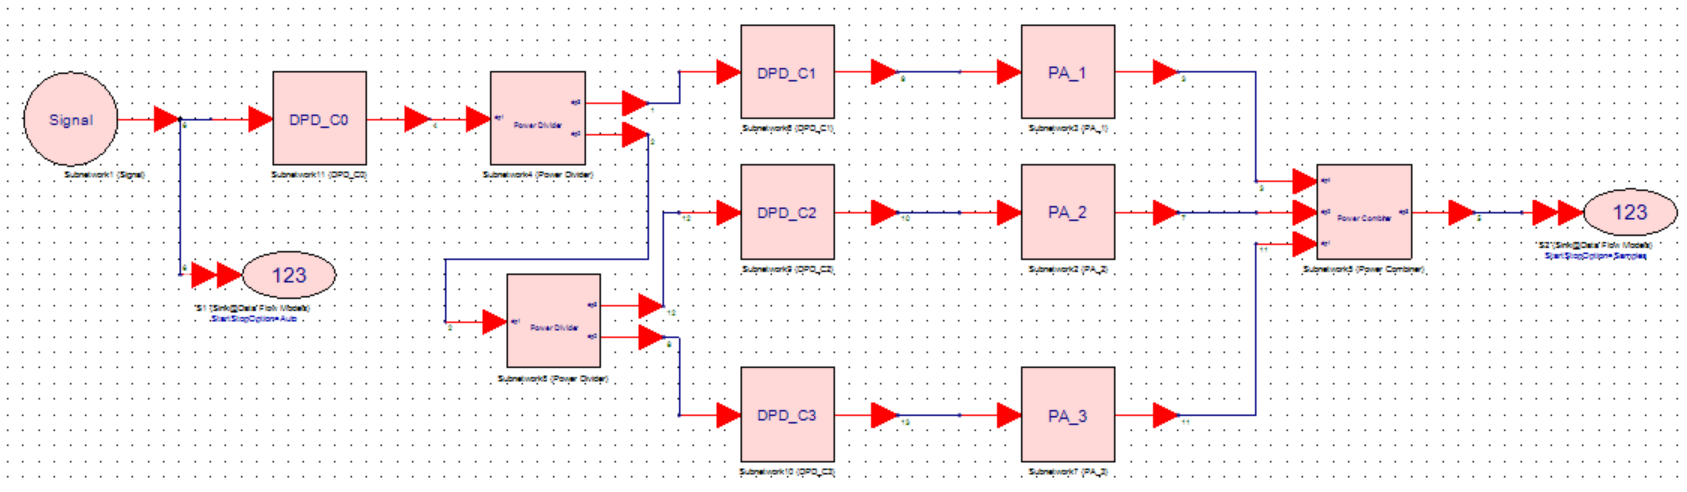

% 运行前请先将子文件夹添加到路径
clc; 

## -----------------------------Model C Train----------------------------

## 读取数据

clear;
% 读取文件并处理数据
[Data_matrix,dim]=ReadFile_Train();
% 根据需要选取原始数据
Sys_input = Data_matrix(:,1) + 1i * Data_matrix(:,2); 
PA1_output = Data_matrix(:,3) + 1i * Data_matrix(:,4); 
PA2_output = Data_matrix(:,5) + 1i * Data_matrix(:,6); 
PA3_output = Data_matrix(:,7) + 1i * Data_matrix(:,8); 
PA1_input = 0.5*Sys_input;
PA2_input = 0.25*Sys_input;
PA3_input = 0.25*Sys_input;
% 参数需要保持一致
M = 4; 

## 【训练PA3】

% % 模型训练
% model=Train_FNN(M,dim,PA3_input,PA3_output,[8,8]);
% save('Method_C\PA3\FNN.mat', 'model');

## 【训练PA2】

% % 模型训练
% model=Train_FNN(M,dim,PA2_input,PA2_output,[16,8,8]);
% save('Method_C\PA2\FNN.mat', 'model');

## 【训练PA1】

｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　轮　　｜　　迭代　　｜　　　　经过的时间　　　　　｜　　小批量　ＲＭＳＥ　　｜　　验证　ＲＭＳＥ　　｜　　小批量损失　　｜　　验证损失　　｜　　基础学习率　　｜
｜　　　　　｜　　　　　　｜　　（ｈｈ：ｍｍ：ｓｓ）　　｜　　　　　　　　　　　　｜　　　　　　　　　　　｜　　　　　　　　　｜　　　　　　　　｜　　　　　　　　　｜
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　　１　｜　　　　１　｜　　　　　００：００：０２　｜　　　　　　　０．９７　｜　　　　　　０．９４　｜　　０．４７１５　｜　０．４３７３　｜　　０．００３０　｜
｜　　５０　｜　　　５０　｜　　　　　００：００：２１　｜　　　　　　　０．８５　｜　　　　　　０．８４　｜　　０．３５７９　｜　０．３５５８　｜　　０．００３０　｜
｜　１００　｜　　１００　｜　　　　　００：００：４４　｜　　　　　　　０．８４　｜　　　　　　０．８４　｜　　０．３５６９　｜　０．３５４７　｜　　０．００３０　｜
｜　１５０　｜　　１５０　｜　　　　　００：０１：０７　｜　　　　　　　０．８４　｜　　　　　　０．８４　｜　　０．３５６５　｜　０．３５４４　｜　　０．００３０　｜
｜　２００　｜　　２００　｜　　　　　００：０１：３０　｜　　　　　　　０．８４　｜　　　　　　０．８４　｜　　０．３５６５　｜　０．３５４４　｜　　０．００３０　｜
｜　２５０　｜　　２５０　｜　　　　　００：０１：５３　｜　　　　　　　０．８４　｜　　　　　　０．８４　｜　　０．３５６４　｜　０．３５４３　｜　　０．００１５　｜
｜　３００　｜　　３００　｜　　　　　００：０２：１６　｜　　　　　　　０．８４　｜　　　　　　０．８４　｜　　０．３５６３　｜　０．３５４２　｜　　０．００１５　｜
｜　３５０　｜　　３５０　｜　　　　　００：０２：４０　｜　　　　　　　０．８４　｜　　　　　　０．８４　｜　　０．３５６３　｜　０．３５４２　｜　　０

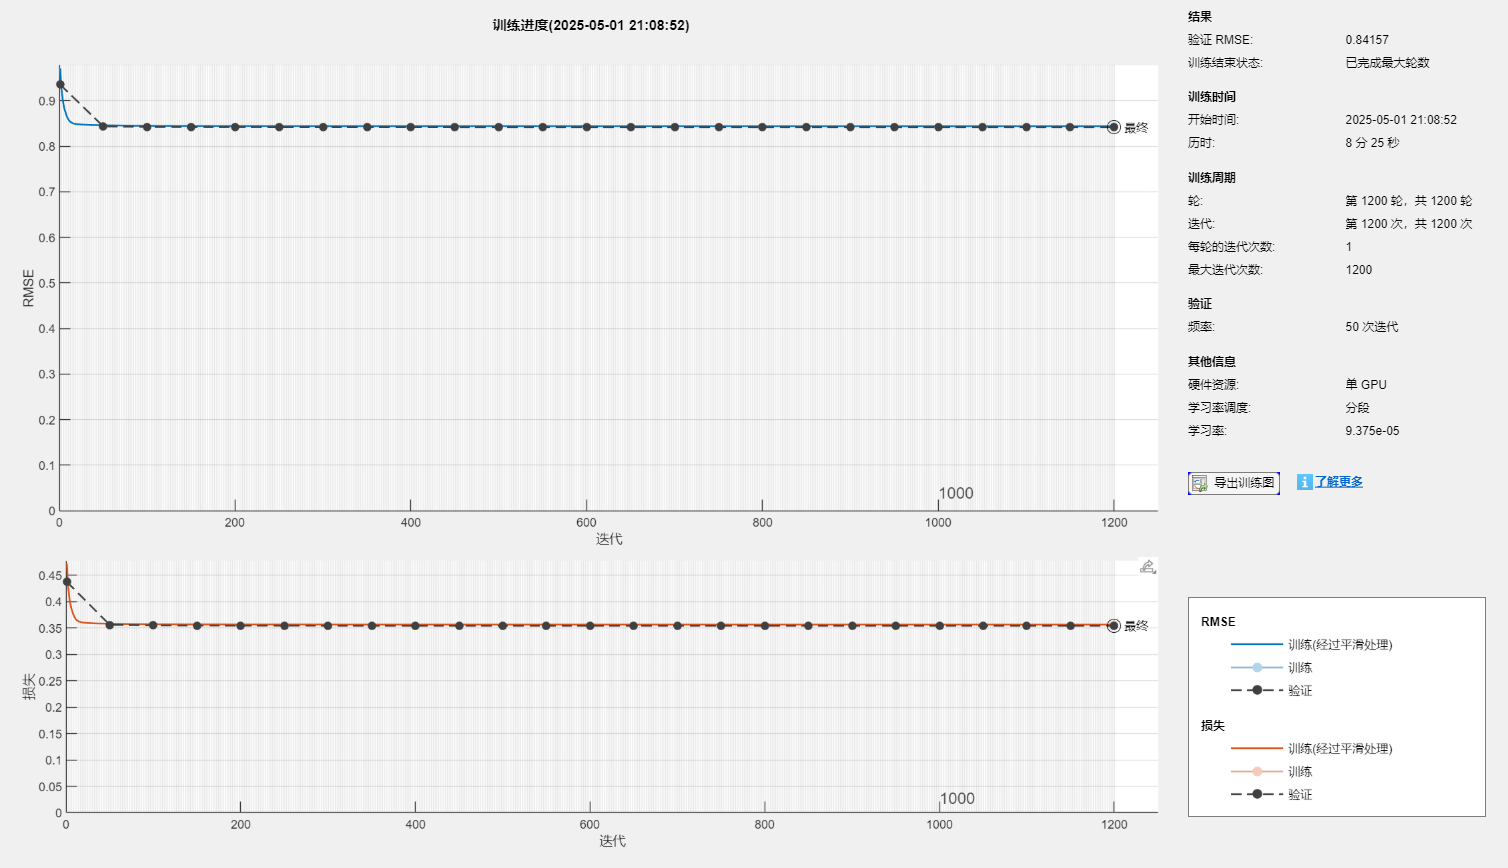

% 训练整体
[X,Y] = pre_train(M,real(PA1_input),imag(PA1_input),real(PA1_output),imag(PA1_output),dim);
% 更多细节可见：https://ww2.mathworks.cn/help/deeplearning/ref/trainingoptions.html
layers = [
    sequenceInputLayer(10,"Name","input")
    lstmLayer(128,"Name","lstm")
    dropoutLayer(0.5,"Name","drop")
    fullyConnectedLayer(8,"Name","fc")
    fullyConnectedLayer(2,"Name","fc2")
    softmaxLayer("Name","softmax")
    regressionLayer("Name","regressionoutput")];

num = 6001;
X_Validation = X(:, num:end);
Y_Validation = Y(:, num:end);
maxEpochs = 1200;
miniBatchSize = 258; %数据处理批次
options = trainingOptions('adam', ...
    'MaxEpochs', maxEpochs, ...                         % 最大训练轮次
    'MiniBatchSize', miniBatchSize, ...                 % 单次迭代（iteration）使用的数据量
    'InitialLearnRate', 0.003, ...                      % 初始学习率
    'GradientThreshold', 1, ...                         % 梯度裁剪阈值，防止梯度爆炸
    'ValidationData', {X_Validation, Y_Validation}, ... % 验证数据集，用于监控模型泛化性能。
    'ValidationFrequency', 50, ...                      % 验证频率
    'ValidationPatience',5,...                          % 若验证损失连续 5 次未改善，则提前停止训练。
    'Shuffle', 'every-epoch', ...                       % 是否打乱数据顺序
    'Plots', 'training-progress', ...                   % 实时绘制训练损失和验证损失曲线
    'ExecutionEnvironment', 'gpu', ...                  % 训练环境
    'LearnRateSchedule', 'piecewise', ...               % 学习率衰减策略（此处为分段衰减）
    'LearnRateDropFactor', 0.5, ...                     % 学习率衰减因子
    'LearnRateDropPeriod', 200, ...                     % 学习率衰减周期
    'Verbose', 1, ...                                   % 是否输出日志
    'VerboseFrequency', 1000);                          % 命令行日志输出频率
% 'Plots', 'none', ...
% 'Shuffle','never', ...

model = trainNetwork(X(:, 1:num), Y(:, 1:num), layers, options);

save('Method_C\PA1\new-LSTM.mat', 'model');

## 第一次迭代

% 系统仿真
[A1_input,A23] = Power_Divider(Sys_input);
[A2_input,A3_input] = Power_Divider(A23);
A1_input_DPD = DPD_predict(A1_input,M,'Method_C\PA1\new-LSTM.mat');
A2_input_DPD = DPD_sim(A2_input,M,'Method_C\PA2\FNN.mat');
A3_input_DPD = DPD_sim(A3_input,M,'Method_C\PA3\FNN.mat');
A1_output = PA_1(A1_input_DPD);
A2_output = PA_2(A2_input_DPD);
A3_output = PA_3(A3_input_DPD);
Sys_output_middle = Power_Combiner(A1_output,A2_output,A3_output);
nmse_middle = NMSE_dB(Sys_input,Sys_output_middle)

nmse_middle = -3.1690

nmse_1 = NMSE_dB(A1_input,A1_output)

nmse_1 = 2.3896

nmse_2 = NMSE_dB(A2_input,A2_output)

nmse_2 = -48.9220

nmse_3 = NMSE_dB(A3_input,A3_output)

nmse_3 = -48.2952

## 【训练】整体优化

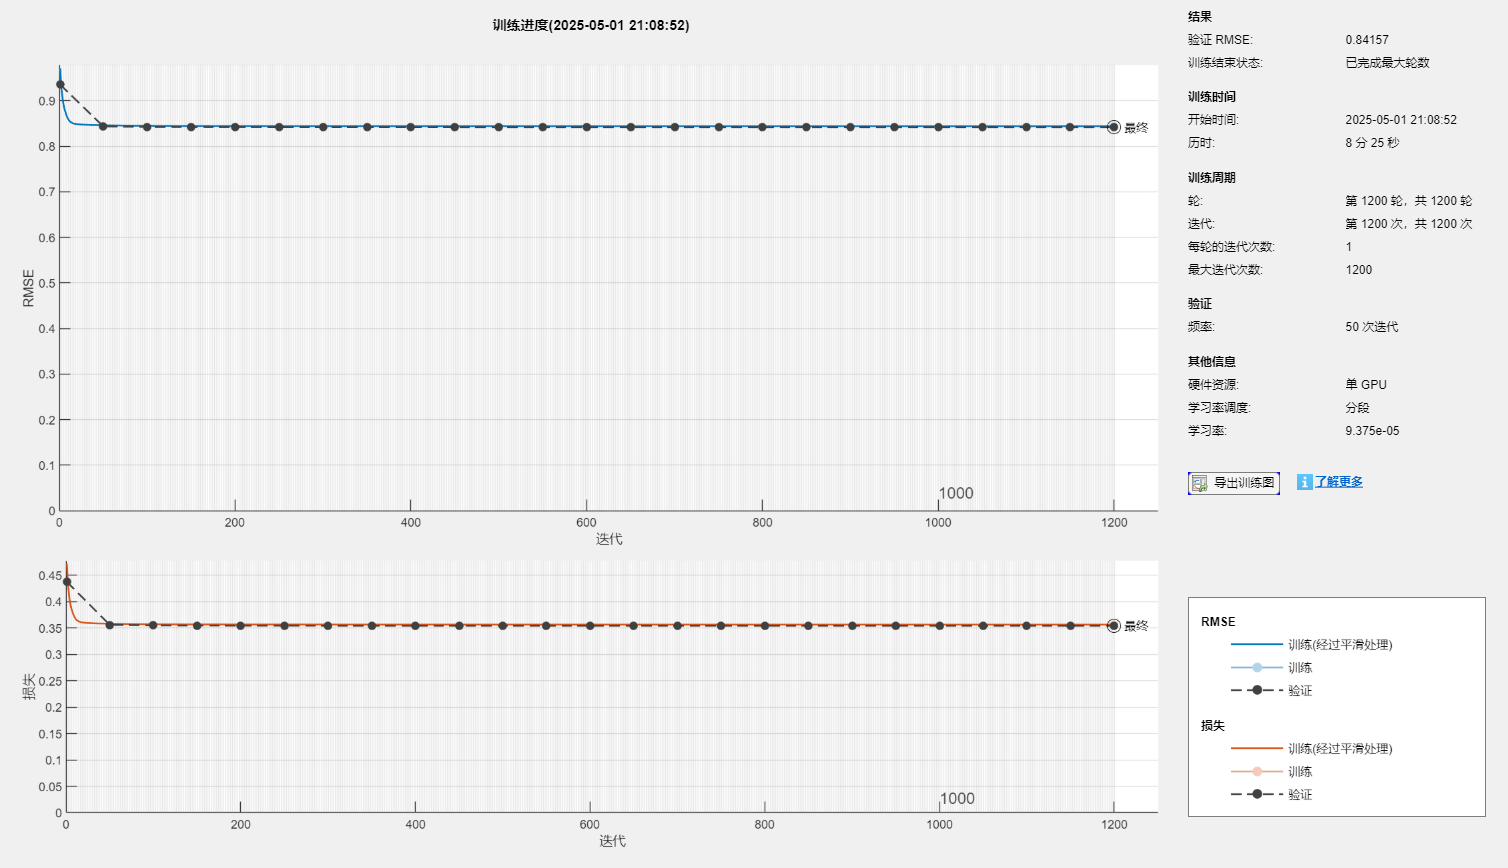

% 模型训练
model=Train_FNN(M,dim,Sys_input,Sys_output_middle,[16,8,8]);

save('Method_C\Whole\FNN.mat', 'model');

## Model Test

% 系统仿真
Sys_input_DPD=DPD_sim(Sys_input,M,'Method_C\Whole\FNN.mat'); % DPD
[A1_input,A23] = Power_Divider(Sys_input_DPD);
[A2_input,A3_input] = Power_Divider(A23);
A1_input_DPD = DPD_predict(A1_input,M,'Method_C\PA1\new-LSTM.mat'); % DPD
A1_output = PA_1(A1_input_DPD);
A2_input_DPD = DPD_sim(A2_input,M,'Method_C\PA2\FNN.mat'); % DPD
A2_output = PA_2(A2_input_DPD);
A3_input_DPD = DPD_sim(A3_input,M,'Method_C\PA3\FNN.mat'); % DPD
A3_output = PA_3(A3_input_DPD);
Sys_output = Power_Combiner(A1_output,A2_output,A3_output);
% 性能评估
nmse = NMSE_dB(Sys_input,Sys_output);
nmse_1 = NMSE_dB(A1_input,A1_output)

nmse_1 = 3.5001

nmse_2 = NMSE_dB(A2_input,A2_output)

nmse_2 = -12.8192

nmse_3 = NMSE_dB(A3_input,A3_output)

nmse_3 = -5.6800

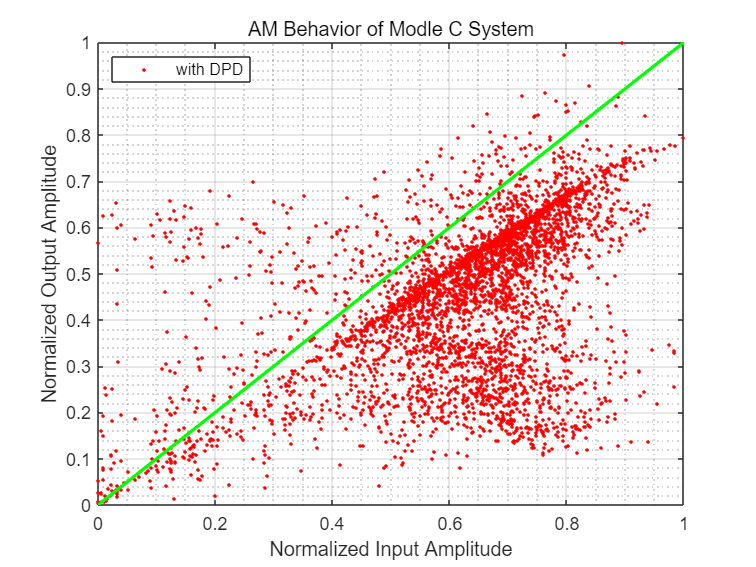

Plot_AM(Sys_input,Sys_output,'AM Behavior of Modle C System','with DPD');

fprintf('使用Model C，系统的NMSE仿真结果为 %f dB\n', nmse);

使用Model C，系统的NMSE仿真结果为 -5.476698 dB



[a,b]=max(abs(Sys_output-Sys_input))

a = 1.8680

b = 2462

## -----------------------------Model C Valid----------------------------

## 读取数据

clear;
% 读取文件并处理数据
[Data_matrix,dim]=ReadFile_Valid();
% 根据需要选取原始数据
Sys_input = Data_matrix(:,1) + 1i * Data_matrix(:,2); 
% 参数需要保持一致
M = 4;

## Model Test

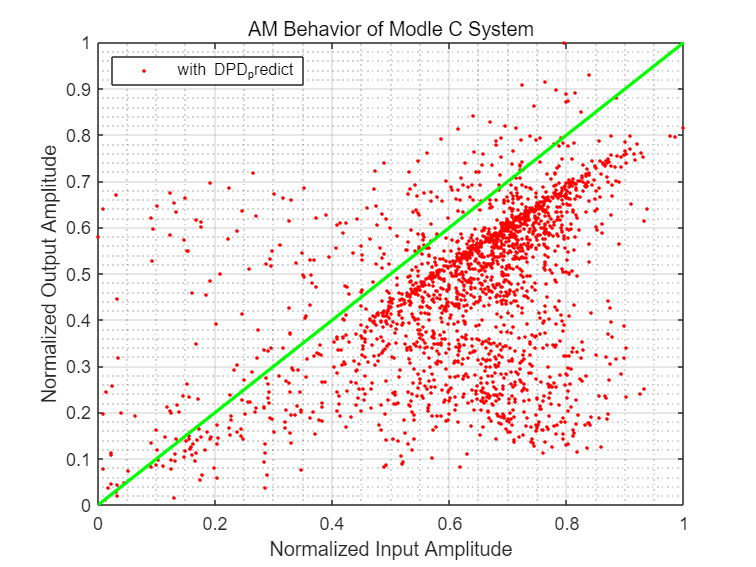

% 系统仿真
Sys_input_DPD=DPD_sim(Sys_input,M,'Method_C\Whole\FNN.mat'); % DPD
[A1_input,A23] = Power_Divider(Sys_input_DPD);
[A2_input,A3_input] = Power_Divider(A23);
A1_input_DPD = DPD_predict(A1_input,M,'Method_C\PA1\new-LSTM.mat'); % DPD
A2_input_DPD = DPD_sim(A2_input,M,'Method_C\PA2\FNN.mat'); % DPD
A3_input_DPD = DPD_sim(A3_input,M,'Method_C\PA3\FNN.mat'); % DPD
A1_output = PA_1(A1_input_DPD);
A2_output = PA_2(A2_input_DPD);
A3_output = PA_3(A3_input_DPD);
Sys_output = Power_Combiner(A1_output,A2_output,A3_output);
% 由于PA和DPD的延时，所以少算（4+2M）个值
Sys_input = Sys_input(5+M*2:end);
Sys_output = Sys_output(5+M*2:end);
% 性能评估
Plot_AM(Sys_input,Sys_output,'AM Behavior of Modle C System','with DPD_predict');

nmse_sim= NMSE_dB(Sys_input,Sys_output);
fprintf('使用Model C，系统的NMSE仿真结果为 %f dB\n', nmse_sim);

使用Model C，系统的NMSE仿真结果为 -5.397621 dB
